# Project - Compare Stellar Spectra

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data from the previous project.

% starData.mat must be in the same folder as file to work

load starData

## Task 1

% removing (:2) to get a vector speed instead of a singular
% [sHa,idx] = min(spectra(:,2));
[sHa,idx] = min(spectra);
lambdaHa = lambda(idx);
z = lambdaHa/656.28 - 1;
speed = z*299792.458

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


## Tasks 2–4

for v = 1:7
    % speed of star
    s = spectra(:,v);
    if speed(v) <= 0
        % Star speed is possitve, it is moving away from the earth
        % Make it dashed
        plot(lambda,s,"--")
    else
        % Star speed is negative, it is moving towards the earth
        % Make it thick
        plot(lambda,s,LineWidth=3) 
    end
    hold on
end
hold off

## Task 5

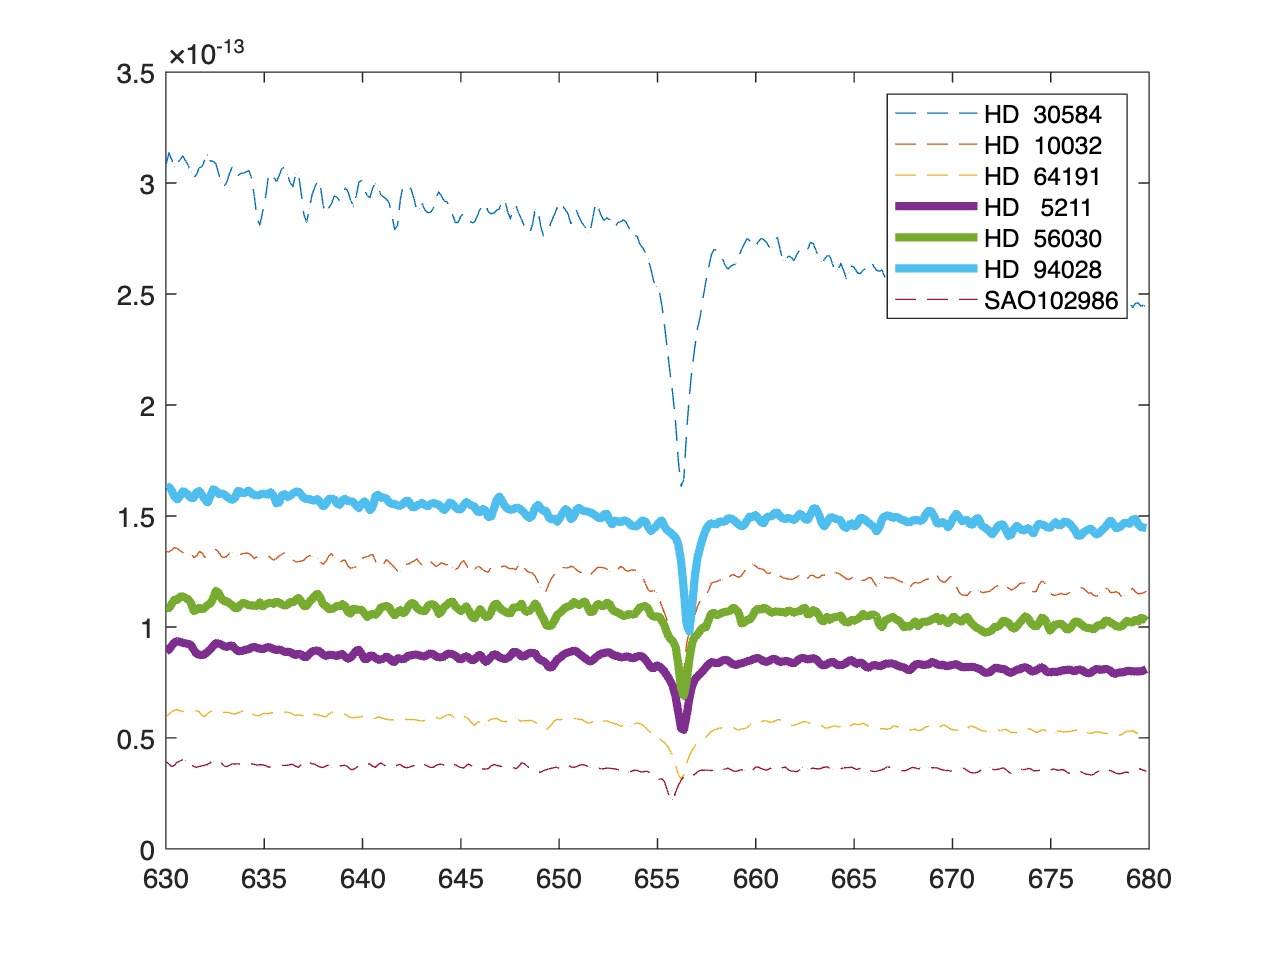

% Adding a legend of the names of each star with their associated colors
% colors are assigned automatically
legend(starnames)

## Task 6

% filter starnames for speeds (corrisponding indexs) more than 0, "moving away"
movaway = starnames(speed > 0) 

movaway = 3x1 string array
    "HD   5211"
    "HD  56030"
    "HD  94028"


## Further Practice

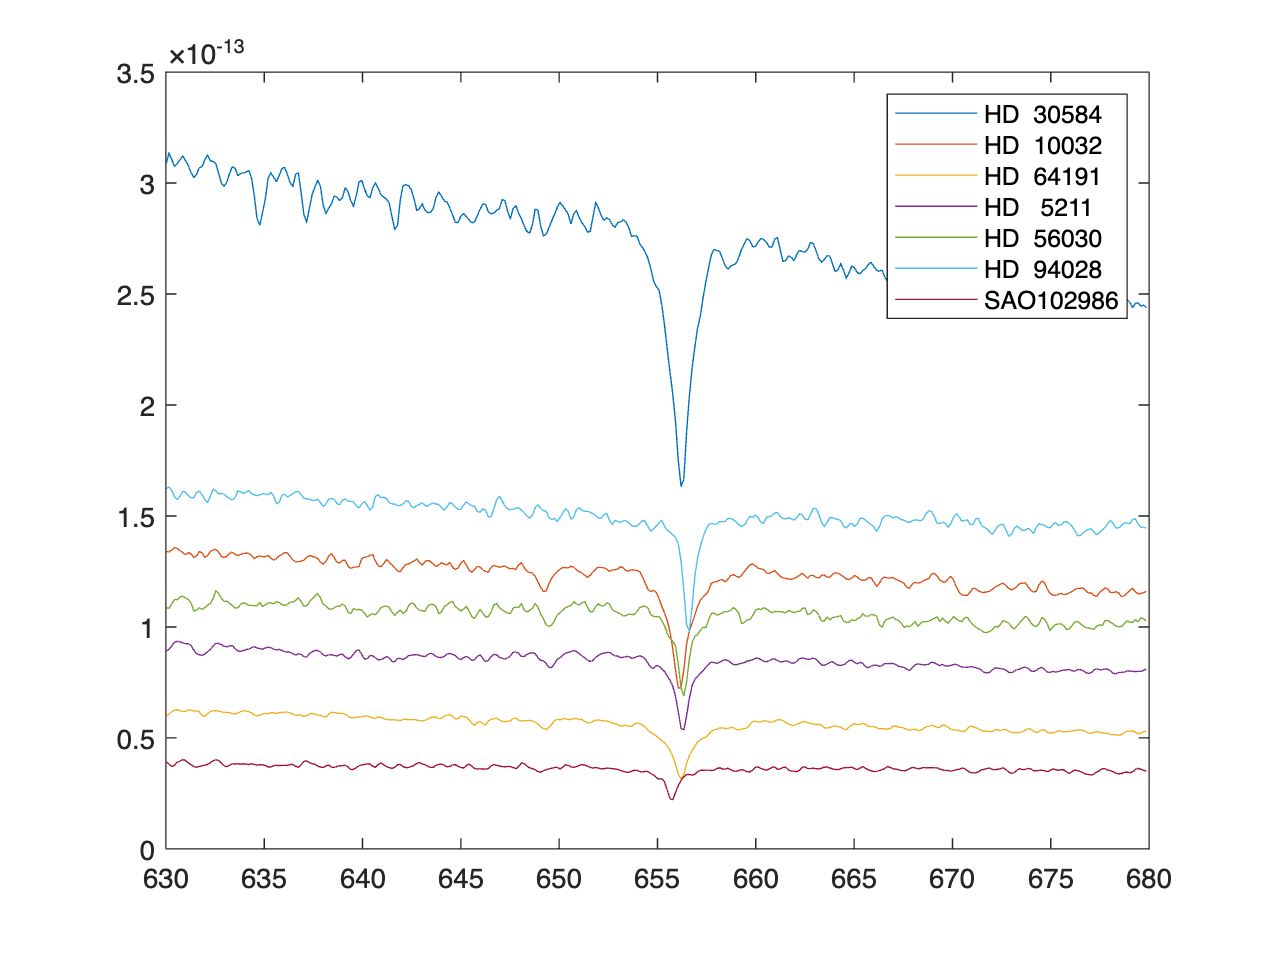

% Quick Alternate to tasks 2-4, but has less formatting
plot(lambda,spectra)
legend(starnames)